testImageIdx = 2

testImageIdx = 2

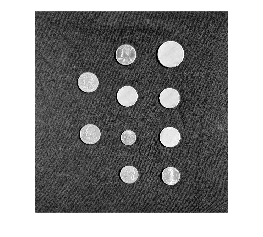

testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure,imshow(testCoinImage)

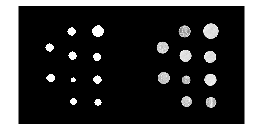


%call segmentation function
[testCoinMask,maskedTestCoinImage]= segmentImageCoinTest(testCoinImage);
se = strel('disk', 15, 6);
testCoinMask = imfill(testCoinMask, 'holes'); % Fill any holes in it.
testCoinMask = imerode(testCoinMask, se); % Shrink by 3 layers of pixels.
maskedTestCoinImage = im2gray(maskedTestCoinImage);
montage({testCoinMask,maskedTestCoinImage})

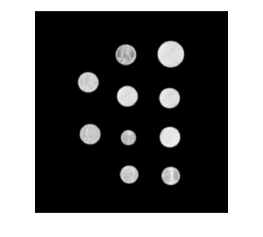

testCoinImageFilt= imgaussfilt(maskedTestCoinImage,3);
imshow(testCoinImageFilt)

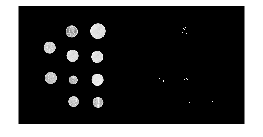

[faceEdgeMask, threshOut] = edge(testCoinImageFilt,"canny",0.08);
faceEdgeMask(~testCoinMask) = 0;
montage({maskedTestCoinImage,faceEdgeMask})

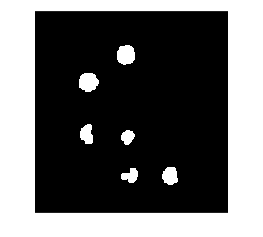

%Passed
faceEdgeMaskDilate = imdilate(faceEdgeMask,se);
imshow(faceEdgeMaskDilate)

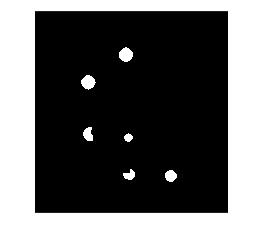

validCoinMask = faceEdgeMaskDilate & testCoinMask;
imshow(validCoinMask)

validCoinMask(~testCoinMask) = 0;
imshow(validCoinMask)